# Foreword and Logistics

For this assignment, I decided to do everything using MATLAB's Live Script feature. Last year we pused Python + Jupyter Notebook and this feels very similar. 

I've created and formatted this livescript with some considerations in mind and you should mimic them for the best possible experience:

- The LiveEditor is open in full screen

- The view is 'Output Inline' (View -> Output Inline)

You will be presented with questions within this file. Just like Assignment 1, you should answer questions as they are presented to you in the corresponding assignment within Gradescope. For this assignment, we will also be referring to files and webpages. When those links are provided, please open them using your favorite browser.

If you run into any problems, please let us know on Piazza!

# Overview

For this assignment, we will be working with a BCI competition dataset, with the primary goal of classifying target vs non-target trials from a  P300 speller. The data we will be using comes from the 2nd Berlin BCI  Competition, and was provided by Wadsworth Center, NYS Department of  Health (Jonathan R. Wolpaw). Please go to the following link:  [http://www.bbci.de/competition/ii/](http://www.bbci.de/competition/ii/)

We will be working with **Dataset IIb**. Please click on  the description of this dataset (pdf format is superior) and read  through the page in order to answer the following questions Here is a direct link: [http://www.bbci.de/competition/ii/albany_desc/albany_desc_ii.pdf](http://www.bbci.de/competition/ii/albany_desc/albany_desc_ii.pdf)

***Question 1:*** What is the frequency of the row/column intensification?                                                                                                                                                                                                                                                                                                                                                                  ***Question 2:*** How long (in ms) was each row/column intensified?                                                                                                                                                                                                                                                                                                                                                        ***Question 3:*** How much time (in ms) was there between each row/column intensification?                                                                                                                                                                                                                                                                                                                ***Question 4:*** What is the sampling rate of the EEG data?                                                                                                                                                                                                                                                                                                                                                                        ***Question 5:*** Within a 180 trial block, how many times is every letter/number intensified?

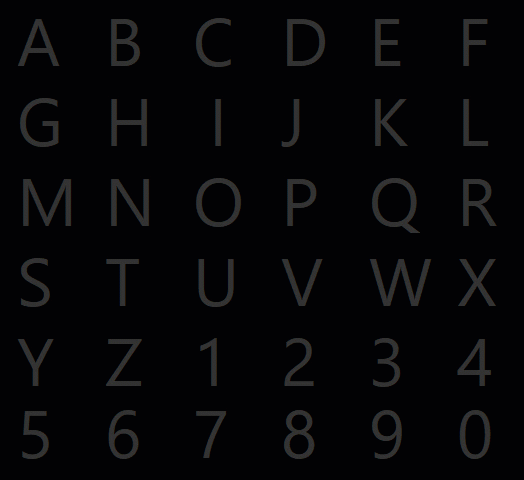

*The .gif above is what the actual task looks like. I created the  animation following the description of the dataset. As you can tell,  these stimuli are being presented in rapid succession. The participant is instructed to only focus on one character at a time, until they are instructed by the task to look at a new character.*

# Section 1

## Loading the Data

The format of the data are inconvenience for working with in EEGLAB. In order to streamline the analysis of this assignment and reduce the confusion of working with an arbitrary data format, I've done the following pre-processing stages to the data:

- Band-pass filtered the raw signals ([0.1 30] Hz Butterworth, 2nd order. Non-causal)

- Combined all of the training data into one EEG set and the testing data into another

- Epoched and baseline corrected the data (Epoched from 0 - 500 ms surrounding stimulus onset; baseline corrected using 0 - 100 ms surrounding stimulus onset)

- Created an EEG dataset which can be loaded into MATLAB

We will need to execute the file which pre-processes the data. This is because we are limited to uploading small file sizes to GitHub. All of the raw data was downloaded from the competition link specified above. You should consider the data hosted here temporary and if it is ever removed, you can download it freely from the link above.

Let's load in our training dataset. We will be using EEGLAB to accomplish this, but not the GUI.

        1. Make sure EEGLAB is added to your MATLAB path (should be from last time)

        2. Run the following line of code and navigate to where you downloaded the files for A2

            (*Note: you can execute code by hovering your cursor just to the left of the code block, or click Ctrl + Enter OR Cmd + Return*)

dir = uigetdir

The variable 'dir' will now be set to the location where we will be loading our files from.

        3. Execute the following lines to initiate eeglab and load the training file

eeglab;
if ~isfile([dir '/testingData.set']) && ~isfile([dir '/trainingData.set'])
    P300_Preprocessing(dir); % pre-process and amalgamate the data if needed (should only run once)
end
EEG = pop_loadset('trainingData.set', dir);
eeglab redraw; % To update the EEGLAB plot to appear below this line

***Question 6:*** How many epochs are in our training dataset?

That's a lot of epochs! In the previous assignment, we had 3 unique events: 'Hi', 0 and 1. With this dataset, we have a unique event for when every row/column is flashed (1-12). In order to make segmenting the data easier in a later space, I used a scheme for denoting which events were **targets** and which were **non-targets**.

- **Target** events follow this structure: 2XXX

- **Non-target** events follow this structure: 1XXX

This means that if the 1st column was illuminated and it was a target, we would get the event code: 2001.

Similarly, if the last row was illuminated and it was a non-target, we would get the event code: 1012

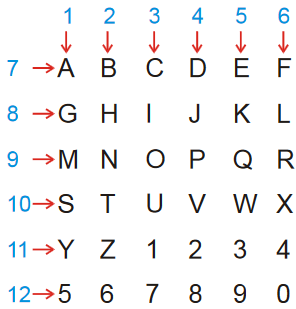

Let's see how many unique events we have. In order to accomplish this, we will have to iterate through a field within a structure. There are more efficient ways to do this, but in order to be transparent with the process, we will be using a simple for loop:

% Extract field values from EEG.event.type into an array 'events'
events = zeros(EEG.trials, 1);       % Create our events array (preallocate memory)
for i = 1:EEG.trials                 % EEG.trials contains the number of epochs/events we have extracted
    events(i) = EEG.event(i).type;   % The actual event label is contained within the field 'type'
end

% We can now extract the unique events
disp(unique(events))

***Question 7: ***Which events are not present in the training data?

# Section 2

## Formatting the Data

Now that we have loaded the data in, we must process the data further in order to effectively train a classifier. We will first seperate the two main types of trials, namely the target and non-target trials, and plot our ERPs. Afterwards, we will reduce the amount of data we will be training our classifier on by taking a windowed mean of our trials. In the previous assignment, we did this using the GUI, but it will be much more efficient to call the commands directly:

% Let's create a target and non-target structures
targets     = pop_epoch(EEG, {'2001' '2002' '2003' '2004' '2005' '2006' '2007' '2008' '2009' '2010' '2011' '2012'}, [0 0.499], 'newname', 'target epochs');
non_targets = pop_epoch(EEG, {'1001' '1002' '1003' '1004' '1005' '1006' '1007' '1008' '1009' '1010' '1011' '1012'}, [0 0.499], 'newname', 'nontarget epochs');

You may have noticed we no longer updated the EEG variable. Because of this, the EEGLAB GUI will not recognize either one of these new structures we have created. Luckily for us, we no longer have any use for the GUI! 

Let's now plot our averaged ERPs using code similar to what we used in the previous assignment.

**Before you can execute the code properly, you will have to fill in a variable, 'ANS1', which is currently set to -9. ANS1 will be multiplied with EEG.xmin and EEG.xmax to create the epoch's starting and ending time in MILLISECONDS, respectively. xmin and xmax store information in the unit seconds. Please fill out ANS1 appropriately so that the resulting multiplications are in MILLISECONDS.**

target_ERP    = mean(targets.data, 3);
nontarget_ERP = mean(non_targets.data, 3);
figure


%----------------------------------
%--    FILL IN THIS VARIABLE     --
%-- vvvvvvvvvvvvvvvvvvvvvvvvvvvv --
%----------------------------------
ANS1 = -9; % <----- Follow the instructions above and fill in this variable
%----------------------------------
%-- ^^^^^^^^^^^^^^^^^^^^^^^^^^^^ --
%--    FILL IN THIS VARIABLE     --
%----------------------------------


epoch_start   = EEG.xmin * ANS1;
epoch_end     = EEG.xmax * ANS1;
sampling_rate = EEG.srate;
ch = 11; % Channel Cz
times = EEG.times;
plot(times, target_ERP(ch, :), 'b');
hold on;
plot(times, nontarget_ERP(ch, :), 'r');
legend('Target', 'Non-Target');
xlabel('Time (ms)');
ylabel(['Amplitude (A/D Units), Channel ' EEG.chanlocs(ch).labels]);

That's a pretty juicy P300! In this case, the component is peaking roughly at 330 ms.

Now that we've seperated our targets and non-targets and visually confirmed we're observing the expected phenomenon, let's further process our data. We will be taking a windowed mean of our data, meaning we will take the average of signals within a certain window or time range. We do this because there is a lot of mutual information temporally and it is not necessary to include all of it when training the classifier. Furthermore, the windowed means allows us to have fewer dimensions in our data and avoid the 'curse of dimensionality.'

We will extract signals from the portion of the epoch relevant to the observed phenomenon. In this case, the data between 250 and 450 ms seems to be the optimal choice. Within this window, we will compute 6 windowed means per trial and channel. The resulting matrix could be written as $$$points$$ x  $$channels$$ x $$epochs$$$ x $$$channels$$$ x $$$epochs$$$, but we can merge the points and channels to have a 2D feature vector for training the classifier.

**Before we execute the following section of code, we will need to fill in the variables ANS2 and ANS3. ANS2 will correspond to the start of the window mentioned in the above paragraph, and ANS3 will correspond to the end of the window mentioned in the above paragraph.**

% Let's take the windowed means of our two classes using the function
% included with the assignment, 'wm189'


%------------------------------------
%--    FILL IN THESE VARIABLES     --
%-- vvvvvvvvvvvvvvvvvvvvvvvvvvvvvv --
%------------------------------------
ANS2 = -9; % <----- Follow the instructions above and fill in this variable
ANS3 = -9; % <----- Follow the instructions above and fill in this variable
%------------------------------------
%-- ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^ --
%--    FILL IN THESE VARIABLES     --
%------------------------------------


window = [ANS2 ANS3];
points = 6;
targets_wm      = wm189(targets,     window, points);
non_targets_wm  = wm189(non_targets, window, points);

Now that we have our data formatted correctly, let's train a classifier!

# Section 3

## Training a Classifier

Let's seperate our training data into a training and validation set. It is important to not include the validation data in your training set as doing so will lead to overfitting. Let's shuffle our targets_wm dataset and seperate it.

**Before we run the following section, we will need to fill in the variable ANS4. We want to use 20% of the data as validation. However, we will need to input the variable as a decimal number between 0 and 1. Please fill out ANS4 accordingly and execute the following block.**

% Seperate data into train and validation after shuffling
targets_wm      = targets_wm(randperm(size(targets_wm, 1)), :);
non_targets_wm  = non_targets_wm(randperm(size(non_targets_wm, 1)), :);


%----------------------------------
%--    FILL IN THIS VARIABLE     --
%-- vvvvvvvvvvvvvvvvvvvvvvvvvvvv --
%----------------------------------
ANS4 = -9; % <----- Follow the instructions above and fill in this variable
%----------------------------------
%-- ^^^^^^^^^^^^^^^^^^^^^^^^^^^^ --
%--    FILL IN THIS VARIABLE     --
%----------------------------------

val_size = ANS4; % Use 20% of the data for validation
train_ix = [floor((1-val_size)*size(targets_wm, 1)), floor((1-val_size)*size(non_targets_wm, 1))];

training_ = [targets_wm(1:train_ix(1), :); non_targets_wm(1:train_ix(2), :)];
validate_ = [targets_wm(train_ix(1)+1:end, :); non_targets_wm(train_ix(2)+1:end, :)];

% Let's also create labels for our classes 
training_labels = [ones(train_ix(1), 1); zeros(train_ix(2), 1)];
validate_labels = [ones(size(targets_wm, 1) - train_ix(1), 1); zeros(size(non_targets_wm, 1) - train_ix(2), 1)];

Now that we have seperated our data, let's train LDA on our training data. 

Recall that we create the project vector $\overrightarrow{w}$ with the following formula: $\overrightarrow{w} =\Sigma^{-1} \left(\overrightarrow{\mu_1 } -\overrightarrow{\mu_0 } \right)$where $\Sigma$is the covariance matrix and $\overrightarrow{\mu_i }$corresponds to class 0 and 1 for i = 0 and 1 respectively. 

Furthermore, we shrink the covariance matrix before calculating $\overrightarrow{w}$ using the formula $\Sigma \left(\gamma \right)=\left(1-\gamma \right)\Sigma +\gamma \textrm{vI}\;$ where:

$\gamma =$shrinking parameter (*in this case hard coded to 0.03)*

$v=\frac{\textrm{trace}\left(\Sigma \right)}{d\;}$ where $d$ represents the dimensionality of the data ($\textrm{size}\left(\Sigma \;,2\right)$) 

$I=\;$identity matrix matching the dimensionality $d$

**Before we run the following section, we will need to fill in the variable ANS5. ANS5 will be our threshold, also a decimal like ANS4. For this case, we will use a threshold of 50%. Please modify the variable and then run the block of code.**

W = LDA(training_, training_labels);
L = [ones(size(validate_, 1), 1) validate_] * W';
P = exp(L) ./ repmat(sum(exp(L),2),[1 2]);


%----------------------------------
%--    FILL IN THIS VARIABLE     --
%-- vvvvvvvvvvvvvvvvvvvvvvvvvvvv --
%----------------------------------
ANS5 = -9; % <----- Follow the instructions above and fill in this variable
%----------------------------------
%-- ^^^^^^^^^^^^^^^^^^^^^^^^^^^^ --
%--    FILL IN THIS VARIABLE     --
%----------------------------------


% Use P to determine class 1 or class 0 (class 0 < threshold, class 1 >= threshold)
threshold = ANS5;
P_class = double(P(:, 1) < threshold); % 1 == target, 0 == non_target
acc = sum(double(P_class == validate_labels)) / size(validate_, 1)

Fantastic! Now that we have validated our classifier, let's train it again using the entirety of the data

W = LDA([targets_wm; non_targets_wm], [ones(size(targets_wm, 1), 1); zeros(size(non_targets_wm, 1), 1)]);

# Section 4

## Classifying the Testing Data

Now  that we have trained a classifier on our training data, let's predict the labels of the testing data. We must first load in the testing data and then computed the windowed means. This time, however, we will not have knowledge of whether or not the stimuli were targets or non-targets. 

EEG = pop_loadset('testingData.set', dir);
eeglab redraw
testing_wm = wm189(EEG, window, points);
L = [ones(size(testing_wm, 1), 1) testing_wm] * W';
P = exp(L) ./ repmat(sum(exp(L),2),[1 2]);
P_class = double(P(:, 1) < threshold); % PREDICTED LABELS - 1 == target, 0 == non_target

Now we have the probability of each stimulus being a target or a non_target! However, is this all of the information we need? We must go through one more step of processing and determine which letter the individual was attending to. We can do this by using our predicted class label and which row/column was intensified using the events structure of our testing dataset to piece together which letters we predict are targets and non-targets! Let's first extract our events and create a useful matrix for handling the row/column to letter conversion:

% Extract events from testing set
testing_events = struct2cell(EEG.event);           % convert all fields into a cell array
testing_events = cell2mat(testing_events(1, :))';  % only save the 'type' into a cell array and convert to a matrix
disp(unique(testing_events'));

% Create 6x6 character matrix
%                 1    2    3    4    5    6
char_matrix =  [['A', 'B', 'C', 'D', 'E', 'F']  % 7
                ['G', 'H', 'I', 'J', 'K', 'L']  % 8
                ['M', 'N', 'O', 'P', 'Q', 'R']  % 9
                ['S', 'T', 'U', 'V', 'W', 'X']  % 10
                ['Y', 'Z', '1', '2', '3', '4']  % 11
                ['5', '6', '7', '8', '9', '0']];% 12 

We know that for each character, each row and column was flashed once,  for a total of 12 flashes per block and this was repeated 15 times. This means that the first 12x15 data points correspond to the first  character, the 2nd 12x15 data point correspond to the second character,  etc. 

Let's examine the first character from the test data

% Define some useful variables
char_breaks = 15 * 12 % number of stimuli per character
c = 1;                % which character we want
c_s = round(char_breaks*(c-1)) + 1;
c_e = round(char_breaks*c);

% Grab our first character's marker, prediction, and confidence
char1_mrks = testing_events(c_s:c_e);
char1_pred = P_class(c_s:c_e);
char1_prob = P(c_s:c_e, 2); % probability of class 1

% Let's merge these
char1 = [char1_mrks, char1_pred, char1_prob];    

We now have an array *char1* which contains 180 stimuli, their  marker (which row/col), their prediction (0, 1 unused), and the  confidence of the prediction (float). Let's sort our char1 by confidence in order to determine which row and column gives us the character that  we believe to be the subject's target.

% Alright, now let's sort them by the 3rd column, the probability
char1_sort = sortrows(char1, 3, 'descend');

% Let's print out the first 5 results
char1_sort(1:5, :)

Of all the flashes, the one with the highest probability (that it  contains a target) is the marker '6' which corresponds to the last column. Our second highest confidence is the marker '7' which corresponds to the first row.

We could simply take the column/row that has the highest single-flash  probability and consider the target character prediction to be the character in that highest confidence row and highest confident column. However, it's possible that those values are outliers. In order to make better use of all the data, we will take the mean of every marker's (row's and column's) probability, and use the row and column with the highest average probability to determine our character:

% Now we will store the average probability value for every row/column
x = zeros(12, 1);
for i = 1:size(x, 1)
    x(i) = mean(char1_sort(char1_sort(:, 1) == i, 2));
end
    
% Now let's print our character!
[~, row] = max(x(7:end));
[~, col] = max(x(1:6));
our_char = char_matrix(row, col);
disp(['Our character is: ' our_char])
% Let's quickly visualize the average probabilities with a bar plot
bar(x)

Excellent! Our classifier predicts that the first character the subject  attended to was the letter 'F'. Let's now use this logic and apply it iteratively to each character in the test data, and print out every character the user attended to:

% Main loop: Iterate through test data by chunking every 15x12 trials per character
%  Nest 1: Calculate mean of character
char_breaks = 15*12;
output_string = '';

for c = 1:round(size(testing_wm, 1) / char_breaks)
    c_s = round(char_breaks*(c-1)) + 1;
    c_e = round(char_breaks*c);
    
    % Grab our first character's marker, prediction, and confidence
    char_mrks = testing_events(c_s:c_e);
    char_pred = P_class(c_s:c_e);
    char_prob = P(c_s:c_e, 2); % probability of class 1
    
    % Let's merge these
    char = [char_mrks, char_pred, char_prob];    
    char_sort = sortrows(char, 3, 'descend'); % sort
    
    % Create our averages
    x = zeros(12, 1);
    for i = 1:size(x, 1)
        x(i) = mean(char_sort(char_sort(:, 1) == i, 2));
    end
        
    % Now let's append our character
    [~, row] = max(x(7:end));
    [~, col] = max(x(1:6));
    our_char = char_matrix(row, col);
    output_string = [output_string our_char ' '];
end
    
% Print our result
disp(output_string)

Since this is a competition dataset, we were obviously not given the  labels to our test set. However, since this competition is very old  (2002), the results are public! 

5 teams got first place in this competition, each with test character  100% accuracy. The added challenge was to minimize the amount of flashes each character was required, but for simplicity we will not do this. 

Since all of these teams were able to determine the desired characters  with 100% accuracy, we can look at one of their write-ups to determine the true labels of the test set.

The approach we took for this assignment was influenced by: [http://www.bbci.de/competition/ii/results/tax_iib_desc.pdf](http://www.bbci.de/competition/ii/results/tax_iib_desc.pdf) so let's compare our result to theirs!

***Question 8:*** What percentage of our test characters were correctly classified?